close("all"); clear; clc;

A = [
    -1,-4;
    4,-1
    ];

b = 0.05;

t = 0:0.02:3*0.02;

X0 = [
    0.9,-0.1;
    1.1,-0.1;
    1.1,0.1;
    0.9,0.1
    ].';

R = reachableSetGirard2005(zonotope2d(X0),A,b,t);

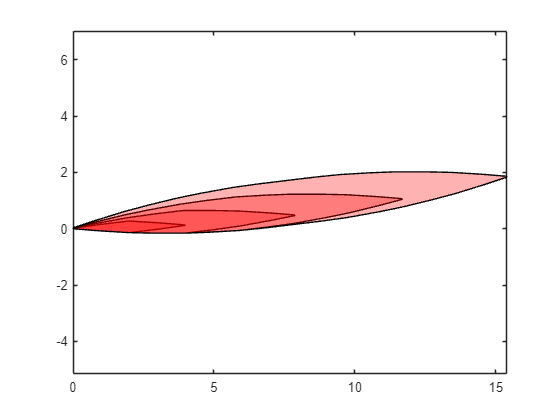

fig = figure();
axe = axes(fig);
arrayfun(@plot,R);
axis(axe,"equal");
box(axe,"on");